clear; clc; close all;

if isempty(gcp('nocreate'))
    numCores = feature('numcores');
    parpool('Processes', min(numCores, 13));  
end

opts = detectImportOptions('Datos_IPC_5a.csv');
opts.VariableNamingRule = 'preserve';
tabla_ipc = readtable('Datos_IPC_5a.csv', opts);

fechas  = tabla_ipc{:, 1};
tickers = tabla_ipc.Properties.VariableNames(2:end);
precios = tabla_ipc{:, 2:end};
[num_dias, num_acciones] = size(precios);

precios = fillmissing(precios, 'previous');
precios = fillmissing(precios, 'nearest');

rendimientos = diff(log(precios));
validos      = all(isfinite(rendimientos), 2);
rendimientos = rendimientos(validos, :);
fechas_r     = fechas(2:end);
fechas_r     = fechas_r(validos);
dias_anio    = 252;

metricas = zeros(num_acciones, 8);

for i = 1:num_acciones
    r_i       = rendimientos(:, i);
    vol_anual = std(r_i) * sqrt(dias_anio);
    ret_anual = mean(r_i) * dias_anio;
    sharpe_i  = (vol_anual > 0) * (ret_anual / vol_anual);

    precios_i   = precios(:, i);
    pico_acum   = cummax(precios_i);
    drawdown    = (precios_i - pico_acum) ./ pico_acum;
    max_dd_i    = abs(min(drawdown));
    skew_i      = skewness(r_i);
    kurt_i      = kurtosis(r_i);
    VaR95_i     = abs(mean(r_i) - norminv(0.05) * std(r_i));
    r_neg       = r_i(r_i < 0);

    if ~isempty(r_neg) && std(r_neg) > 0
        sortino_i = ret_anual / (std(r_neg) * sqrt(dias_anio));
    else
        sortino_i = sharpe_i;
    end

    metricas(i, :) = [vol_anual, ret_anual, sharpe_i, max_dd_i, skew_i, kurt_i, VaR95_i, sortino_i];
end

X_base = metricas(:, [1, 4, 7, 6, 3]);  
X_base(:, 5) = -X_base(:, 5);          

media_X = mean(X_base, 1);
sigma_X = std(X_base, 0, 1);
X_norm  = (X_base - media_X) ./ sigma_X;

[coef_pca, X_pca, autovalores] = pca(X_norm); 
var_exp = autovalores ./ sum(autovalores);     

vol    = metricas(:, 1) * 100;
mdd    = metricas(:, 4) * 100;
var95  = metricas(:, 7) * 100;
sharpe = metricas(:, 3);

vol_s    = normalizar01(vol);
mdd_s    = normalizar01(mdd);
var_s    = normalizar01(var95);
sharpe_s = normalizar01(max(sharpe) - sharpe);

score_riesgo = 0.35 * vol_s + 0.25 * mdd_s + 0.25 * var_s + 0.15 * sharpe_s;
percentiles   = prctile(score_riesgo, [25, 50, 75]);

y_verdad = zeros(num_acciones, 1);
for i = 1:num_acciones
    if score_riesgo(i) <= percentiles(1)
        y_verdad(i) = 1;
    elseif score_riesgo(i) <= percentiles(2)
        y_verdad(i) = 2;
    elseif score_riesgo(i) <= percentiles(3)
        y_verdad(i) = 3;
    else
        y_verdad(i) = 4;
    end
end

niveles_riesgo = {'Conservador', 'Moderado', 'Arriesgado', 'Muy Arriesgado'};
K = 4;

rng(42);
datos_red = X_norm';
warning('off', 'all');

red_comp = competlayer(K);
red_comp.trainParam.epochs     = 500;
red_comp.trainParam.showWindow = false;
red_comp = train(red_comp, datos_red);
Y_comp   = red_comp(datos_red);
cl_red   = vec2ind(Y_comp)';
cl_red   = mapearClustersAGroundTruth(cl_red, y_verdad, K);

pesos_red_comp = red_comp.IW{1};

som_dim           = [2 2];
som_net           = selforgmap(som_dim);
som_net.trainParam.epochs     = 500;
som_net.trainParam.showWindow = false;
som_net = train(som_net, datos_red);
Y_som  = som_net(datos_red);
cl_som = vec2ind(Y_som)';
cl_som = mapearClustersAGroundTruth(cl_som, y_verdad, K);

pesos_som      = som_net.IW{1};
posiciones_som = som_net.layers{1}.positions; 
[cl_kmeans, centroides_kmeans] = kmeans(X_norm, K, 'Replicates', 30, 'MaxIter', 1000); %#ok<ASGLU>
cl_kmeans = mapearClustersAGroundTruth(cl_kmeans, y_verdad, K);

try
    gmm = fitgmdist(X_norm, K, 'CovarianceType', 'full', ...
        'RegularizationValue', 0.01, 'Replicates', 10, ...
        'Options', statset('MaxIter', 500, 'TolFun', 1e-6));
    cl_gmm = cluster(gmm, X_norm);
catch
    gmm = fitgmdist(X_norm, K, 'CovarianceType', 'diagonal', ...
        'RegularizationValue', 0.05, ...
        'Options', statset('MaxIter', 1000));
    cl_gmm = cluster(gmm, X_norm);
end
cl_gmm = mapearClustersAGroundTruth(cl_gmm, y_verdad, K);

Z      = linkage(X_norm, 'ward');
cl_jer = cluster(Z, 'maxclust', K);
cl_jer = mapearClustersAGroundTruth(cl_jer, y_verdad, K);

[centros_fcm, U_fcm] = fcm(X_norm, K, [2.0, 300, 1e-5, 0]); 
[~, cl_fcm] = max(U_fcm);
cl_fcm      = cl_fcm(:);
cl_fcm      = mapearClustersAGroundTruth(cl_fcm, y_verdad, K);

warning('on', 'all');

matriz_clusters = [cl_red, cl_som, cl_kmeans, cl_gmm, cl_jer, cl_fcm];
[pesos_red_pso, cl_red_pso, acc_red_pso, sil_red_pso] = optimizarRedCompetitiva_PSO(X_norm, y_verdad, K); %#ok<ASGLU>
[pesos_ens_ga, cl_ens_ga, acc_ens_ga, sil_ens_ga]     = optimizarEnsambleClustering_GA(matriz_clusters, X_norm, y_verdad, K); %#ok<ASGLU>
[cl_ensemble_pso, pesos_ensemble_pso, ~]             = optimizarEnsembleClusteringPSO(matriz_clusters, X_norm, y_verdad); %#ok<ASGLU>

exactitud_ens_pso  = sum(cl_ensemble_pso == y_verdad) / num_acciones;
silhouette_ens_pso = mean(silhouette(X_norm, cl_ensemble_pso));

modelos_total = {'RedCompetitiva','SOM','KMeans','GMM','Jerarquico','FCM','EnsemblePSO','RedCompPSO','EnsembleGA'};

exactitudes_total = [ ...
    sum(cl_red      == y_verdad)/num_acciones; ...
    sum(cl_som      == y_verdad)/num_acciones; ...
    sum(cl_kmeans   == y_verdad)/num_acciones; ...
    sum(cl_gmm      == y_verdad)/num_acciones; ...
    sum(cl_jer      == y_verdad)/num_acciones; ...
    sum(cl_fcm      == y_verdad)/num_acciones; ...
    exactitud_ens_pso; ...
    acc_red_pso; ...
    acc_ens_ga];

silhouettes_total = [ ...
    mean(silhouette(X_norm, cl_red)); ...
    mean(silhouette(X_norm, cl_som)); ...
    mean(silhouette(X_norm, cl_kmeans)); ...
    mean(silhouette(X_norm, cl_gmm)); ...
    mean(silhouette(X_norm, cl_jer)); ...
    mean(silhouette(X_norm, cl_fcm)); ...
    silhouette_ens_pso; ...
    sil_red_pso; ...
    sil_ens_ga];

tabla_clustering = table(modelos_total', exactitudes_total, silhouettes_total, ...
    'VariableNames', {'Modelo','Exactitud','Silhouette'});
disp(tabla_clustering);

          Modelo          Exactitud    Silhouette
    __________________    _________    __________

    {'RedCompetitiva'}     0.83333      0.24269  
    {'SOM'           }     0.58333       0.5701  
    {'KMeans'        }     0.55556      0.58168  
    {'GMM'           }     0.52778      0.28645  
    {'Jerarquico'    }     0.47222       0.5326  
    {'FCM'           }     0.55556       0.3313  
    {'EnsemblePSO'   }     0.83333      0.24269  
    {'RedCompPSO'    }     0.91667      0.21864  
    {'EnsembleGA'    }     0.83333      0.24269  




modelos_clusters = { ...
    cl_red, cl_som, cl_kmeans, cl_gmm, ...
    cl_jer, cl_fcm, cl_ensemble_pso, cl_red_pso, cl_ens_ga};

metricas_clasificacion = struct();
for m = 1:length(modelos_total)
    nombre = modelos_total{m};
    y_pred = modelos_clusters{m};

    [accuracy, precision, recall, f1, ...
     prec_macro, rec_macro, f1_macro, ...
     ~, ~, ~, mat_conf] = calcularMetricasClasificacion(y_verdad, y_pred, K);

    metricas_clasificacion.(nombre) = struct( ...
        'accuracy', accuracy, 'precision', precision, 'recall', recall, 'f1', f1, ...
        'precision_macro', prec_macro, 'recall_macro', rec_macro, 'f1_macro', f1_macro, ...
        'matriz_confusion', mat_conf);
end

fprintf('\nMODELO\t\t\tACCURACY\tPRECISION\tRECALL\t\tF1-SCORE\n');


MODELO			ACCURACY	PRECISION	RECALL		F1-SCORE


for m = 1:length(modelos_total)
    met = metricas_clasificacion.(modelos_total{m});
    fprintf('%-16s\t%.2f%%\t\t%.2f%%\t\t%.2f%%\t\t%.4f\n', modelos_total{m}, ...
        met.accuracy*100, met.precision_macro*100, met.recall_macro*100, met.f1_macro);
end

RedCompetitiva  	83.33%		83.54%		83.33%		0.8331
SOM             	58.33%		48.33%		58.33%		0.4970
KMeans          	55.56%		46.25%		55.56%		0.4629
GMM             	52.78%		44.41%		52.78%		0.4663
Jerarquico      	47.22%		42.73%		47.22%		0.4057
FCM             	55.56%		50.09%		55.56%		0.5180
EnsemblePSO     	83.33%		83.54%		83.33%		0.8331
RedCompPSO      	91.67%		91.94%		91.67%		0.9166
EnsembleGA      	83.33%		83.54%		83.33%		0.8331



[~, idx_mejor] = max(cellfun(@(n) metricas_clasificacion.(n).f1_macro, modelos_total));
modelo_mejor   = modelos_total{idx_mejor};
cluster_final  = modelos_clusters{idx_mejor};
met_mejor      = metricas_clasificacion.(modelo_mejor);

fprintf('\nMejor modelo: %s (F1=%.4f)\n', modelo_mejor, met_mejor.f1_macro);


Mejor modelo: RedCompPSO (F1=0.9166)


fprintf('\nMétricas por clase:\n');


Métricas por clase:


for k = 1:K
    fprintf('%s: Precision=%.2f%%, Recall=%.2f%%, F1=%.4f\n', niveles_riesgo{k}, ...
        met_mejor.precision(k)*100, met_mejor.recall(k)*100, met_mejor.f1(k));
end

Conservador: Precision=90.00%, Recall=100.00%, F1=0.9474
Moderado: Precision=88.89%, Recall=88.89%, F1=0.8889
Arriesgado: Precision=88.89%, Recall=88.89%, F1=0.8889
Muy Arriesgado: Precision=100.00%, Recall=88.89%, F1=0.9412



cluster_seleccionado = [];
for c_pref = 1:4
    if sum(cluster_final == c_pref) >= 2
        cluster_seleccionado = c_pref;
        break;
    end
end

indices_cluster  = find(cluster_final == cluster_seleccionado);
sharpe_cluster   = metricas(indices_cluster, 3);
[~, orden_sh]    = sort(sharpe_cluster, 'descend');
indices_sel      = indices_cluster(orden_sh(1:2));

activos_sel      = tickers(indices_sel);
precios_sel      = precios(:, indices_sel);
rendimientos_sel = rendimientos(:, indices_sel);

fprintf('\nActivos seleccionados: %s, %s\n', activos_sel{1}, activos_sel{2});


Activos seleccionados: CHDRAUIB.MX, AC.MX



media_anual = mean(rendimientos_sel,1)' * dias_anio;
cov_anual   = cov(rendimientos_sel) * dias_anio;

num_port   = 5000;
resultados = zeros(num_port, 4);
pesos_mc   = zeros(num_port, 2);

parfor i = 1:num_port
    w  = rand(2,1);
    w  = w / sum(w);
    r_p = w' * media_anual;
    s_p = sqrt(w' * cov_anual * w);
    sr  = r_p / s_p;
    resultados(i,:) = [r_p, s_p, sr, w(1)];
    pesos_mc(i,:)   = w';
end

[~, idx_max_sr]  = max(resultados(:,3));
w_markowitz      = pesos_mc(idx_max_sr,:)';
ret_markowitz    = resultados(idx_max_sr,1);
vol_markowitz    = resultados(idx_max_sr,2);
sharpe_markowitz = resultados(idx_max_sr,3);

num_particulas = 100;
dim            = 2;
max_iter_pso   = 300;

fitness_portafolio = @(w) calcularSharpe(w, media_anual, cov_anual);

particulas = rand(num_particulas, dim);
particulas = particulas ./ sum(particulas, 2);
velocidades = zeros(num_particulas, dim);

fitness_p = zeros(num_particulas, 1);
for i = 1:num_particulas
    fitness_p(i) = fitness_portafolio(particulas(i,:)');
end

pbest     = particulas;
pbest_fit = fitness_p;
[gbest_fit, idx_best] = max(pbest_fit);
gbest     = pbest(idx_best,:);
hist_pso_port = zeros(max_iter_pso, 1);

for it = 1:max_iter_pso
    w_inercia = 0.9 - 0.5 * it / max_iter_pso;
    for i = 1:num_particulas
        r1 = rand(1, dim);
        r2 = rand(1, dim);
        velocidades(i,:) = w_inercia * velocidades(i,:) + ...
            2.05 * r1 .* (pbest(i,:) - particulas(i,:)) + ...
            2.05 * r2 .* (gbest - particulas(i,:));

        particulas(i,:) = particulas(i,:) + velocidades(i,:);
        particulas(i,:) = max(particulas(i,:), 0.01);
        particulas(i,:) = min(particulas(i,:), 0.99);
        particulas(i,:) = particulas(i,:) / sum(particulas(i,:));

        fit_i = fitness_portafolio(particulas(i,:)');
        if fit_i > pbest_fit(i)
            pbest(i,:)     = particulas(i,:);
            pbest_fit(i)   = fit_i;
            if fit_i > gbest_fit
                gbest     = particulas(i,:);
                gbest_fit = fit_i;
            end
        end
    end
    hist_pso_port(it) = gbest_fit;
end

w_pso      = gbest';
ret_pso    = w_pso' * media_anual;
vol_pso    = sqrt(w_pso' * cov_anual * w_pso);
sharpe_pso = ret_pso / vol_pso;

fprintf('\nMarkowitz: w1=%.2f%%, w2=%.2f%%, Sharpe=%.4f\n', w_markowitz(1)*100, w_markowitz(2)*100, sharpe_markowitz);


Markowitz: w1=61.43%, w2=38.57%, Sharpe=1.0953


fprintf('PSO:       w1=%.2f%%, w2=%.2f%%, Sharpe=%.4f\n', w_pso(1)*100, w_pso(2)*100, sharpe_pso);

PSO:       w1=61.43%, w2=38.57%, Sharpe=1.0953



ret_port_mark = rendimientos_sel * w_markowitz;
ret_port_pso  = rendimientos_sel * w_pso;
valor_inicial = 100;
valor_mark    = valor_inicial * cumprod(1 + ret_port_mark);
valor_pso     = valor_inicial * cumprod(1 + ret_port_pso);

ventana              = 10;
metricas_prediccion  = struct();
predicciones         = struct();
historial_J          = struct();
historial_rnn        = struct(); 

for a = 1:2
    ticker_activo = activos_sel{a};
    campo_ticker  = matlab.lang.makeValidName(strrep(ticker_activo, '.', '_'));
    precios_a     = precios_sel(:, a);

    n_total = numel(precios_a);
    n_train = floor(0.8 * n_total);

    precios_train = precios_a(1:n_train);
    precios_test  = precios_a(n_train+1:end);

    min_p = min(precios_train);
    max_p = max(precios_train);
    den_p = max_p - min_p;
    if den_p == 0
        den_p = 1;
    end

    precios_train_n = (precios_train - min_p) / den_p;
    precios_test_n  = (precios_test  - min_p) / den_p;

    [X_train, y_train] = crearDatasetTemporal(precios_train_n, ventana);

    precios_total_n = [precios_train_n; precios_test_n];
    [X_test, y_test] = crearDatasetTemporalTest(precios_total_n, ventana, n_train);

    lambda = 0.01;
    lr     = 0.005;
    epochs = 3000;

    [w_adaline, b_adaline, hist_J] = entrenarADALINE_J(X_train, y_train, lr, epochs, lambda);

    y_pred_a   = X_test * w_adaline + b_adaline;
    y_real     = y_test * den_p + min_p;
    y_pred_a_r = y_pred_a * den_p + min_p;

    [J_train, J_test] = funcion_costo_J(X_train, y_train, X_test, y_test, w_adaline, b_adaline, lambda);
    [mse_a, rmse_a, mae_a, r2_a, mape_a] = calcularMetricas(y_real, y_pred_a_r);

    historial_J.(campo_ticker) = hist_J;
    warning('off', 'all');
    net = feedforwardnet([16 8], 'trainlm');
    net.trainParam.epochs     = 300;
    net.trainParam.showWindow = false;
    net.trainParam.max_fail   = 30;
    net.performParam.regularization = 0.1;
    net.divideParam.trainRatio = 0.85;
    net.divideParam.valRatio   = 0.15;
    net.divideParam.testRatio  = 0;

    [net, tr_mlp] = train(net, X_train', y_train'); 

    y_pred_m   = net(X_test')';
    y_pred_m_r = y_pred_m * den_p + min_p;
    [mse_m, rmse_m, mae_m, r2_m, mape_m] = calcularMetricas(y_real, y_pred_m_r);
    N_train_seq  = size(X_train, 1);
    X_train_lstm = cell(N_train_seq, 1);
    for i = 1:N_train_seq
        X_train_lstm{i} = X_train(i, :)';   
    end

    N_test_seq = size(X_test, 1);
    X_test_lstm = cell(N_test_seq, 1);
    for i = 1:N_test_seq
        X_test_lstm{i} = X_test(i, :)';    
    end

    numFeatures    = 1;
    numHiddenUnits = 32;

    layers_lstm = [ ...
        sequenceInputLayer(numFeatures)
        lstmLayer(numHiddenUnits, OutputMode="last")
        fullyConnectedLayer(1)];

    options_lstm = trainingOptions('adam', ...
        'MaxEpochs', 50, ...
        'MiniBatchSize', 32, ...
        'InitialLearnRate', 0.01, ...
        'GradientThreshold', 1, ...
        'Shuffle', 'every-epoch', ...
        'Verbose', false, ...
        'Plots', 'none');

    net_lstm = trainnet(X_train_lstm, y_train, layers_lstm, "mse", options_lstm);

    y_pred_lstm = minibatchpredict(net_lstm, X_test_lstm);
    y_pred_lstm = y_pred_lstm(:);
    y_pred_lstm_r = y_pred_lstm * den_p + min_p;
    [mse_lstm, rmse_lstm, mae_lstm, r2_lstm, mape_lstm] = calcularMetricas(y_real, y_pred_lstm_r);

    warning('on', 'all');

    [mse_rw, rmse_rw, mae_rw, r2_rw, mape_rw, ...
     mse_ma, rmse_ma, mae_ma, r2_ma, mape_ma] = ...
        baselinesSerie(precios_a, ventana, n_train, min_p, max_p);

    ventana_final_seq = precios_total_n(end-ventana+1:end);
    pred_a_sig_r = (ventana_final_seq' * w_adaline + b_adaline) * den_p + min_p;
    pred_m_sig_r = net(ventana_final_seq) * den_p + min_p;

    ventana_final_lstm = {ventana_final_seq};  
    pred_lstm_sig = minibatchpredict(net_lstm, ventana_final_lstm);
    pred_lstm_sig = pred_lstm_sig(:);
    pred_lstm_sig_r = pred_lstm_sig * den_p + min_p;

    metricas_prediccion.([campo_ticker '_ADALINE']) = struct( ...
        'MSE', mse_a, 'RMSE', rmse_a, 'MAE', mae_a, 'R2', r2_a, 'MAPE', mape_a, ...
        'J_train', J_train, 'J_test', J_test);

    metricas_prediccion.([campo_ticker '_MLP']) = struct( ...
        'MSE', mse_m, 'RMSE', rmse_m, 'MAE', mae_m, 'R2', r2_m, 'MAPE', mape_m);

    metricas_prediccion.([campo_ticker '_LSTM']) = struct( ...
        'MSE', mse_lstm, 'RMSE', rmse_lstm, 'MAE', mae_lstm, 'R2', r2_lstm, 'MAPE', mape_lstm);

    metricas_prediccion.([campo_ticker '_RW']) = struct( ...
        'MSE', mse_rw, 'RMSE', rmse_rw, 'MAE', mae_rw, 'R2', r2_rw, 'MAPE', mape_rw);

    metricas_prediccion.([campo_ticker '_MA']) = struct( ...
        'MSE', mse_ma, 'RMSE', rmse_ma, 'MAE', mae_ma, 'R2', r2_ma, 'MAPE', mape_ma);

    predicciones.(campo_ticker) = struct( ...
        'real', y_real, ...
        'pred_adaline', y_pred_a_r, ...
        'pred_mlp',     y_pred_m_r, ...
        'pred_lstm',    y_pred_lstm_r, ...
        'pred_sig_adaline', pred_a_sig_r, ...
        'pred_sig_mlp',     pred_m_sig_r, ...
        'pred_sig_lstm',    pred_lstm_sig_r, ...
        'precio_actual',    precios_a(end));

    fprintf('\n%s:\n', ticker_activo);
    fprintf('  ADALINE: R2=%.4f, MAPE=%.2f%%\n', r2_a,   mape_a);
    fprintf('  MLP:     R2=%.4f, MAPE=%.2f%%\n', r2_m,   mape_m);
    fprintf('  LSTM:    R2=%.4f, MAPE=%.2f%%\n', r2_lstm, mape_lstm);
    fprintf('  RW:      R2=%.4f, MAPE=%.2f%%\n', r2_rw,  mape_rw);
    fprintf('  MA:      R2=%.4f, MAPE=%.2f%%\n', r2_ma,  mape_ma);
end


CHDRAUIB.MX:


  ADALINE: R2=0.9131, MAPE=2.20%


  MLP:     R2=0.7029, MAPE=4.40%


  LSTM:    R2=0.9060, MAPE=2.33%


  RW:      R2=1.0000, MAPE=0.00%


  MA:      R2=0.9371, MAPE=1.87%



AC.MX:


  ADALINE: R2=0.8972, MAPE=1.86%


  MLP:     R2=-1.1833, MAPE=9.78%


  LSTM:    R2=0.8242, MAPE=2.57%


  RW:      R2=1.0000, MAPE=0.00%


  MA:      R2=0.9214, MAPE=1.62%


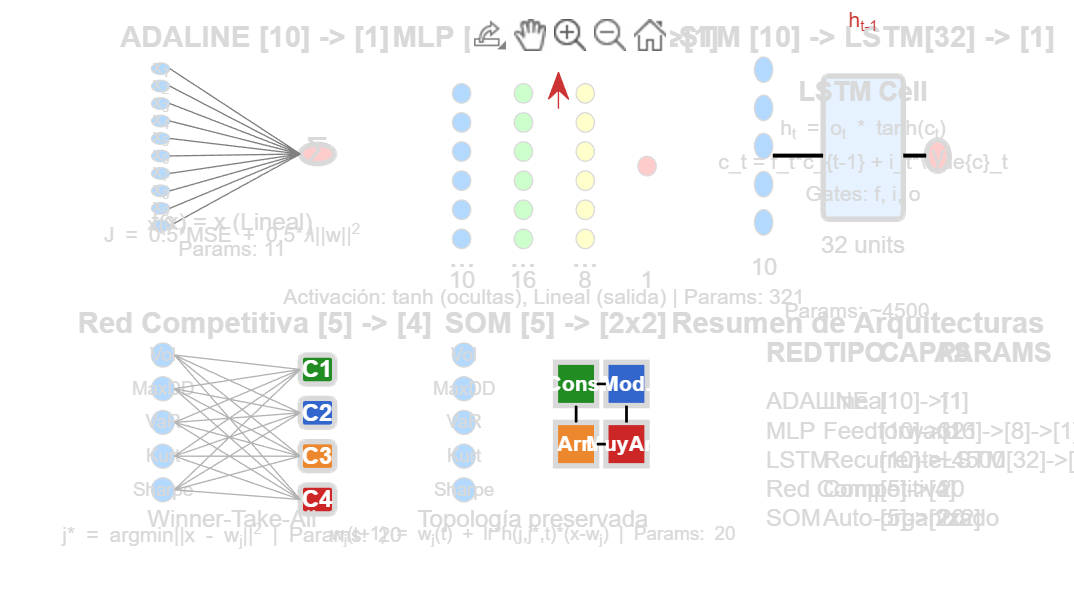


campos_pred = fieldnames(predicciones);

colores = [0.13 0.55 0.13; 0.20 0.40 0.80; 0.93 0.53 0.18; 0.80 0.15 0.15];

figure('Position', [50 50 1600 900], 'Color', 'w');

subplot(2,3,1); hold on; axis off;
title('ADALINE [10] -> [1]', 'FontSize', 11, 'FontWeight', 'bold');
for i = 1:10
    rectangle('Position', [0.05, 1-i*0.09, 0.08, 0.06], 'Curvature', [1 1], 'FaceColor', [0.7 0.85 1]);
    text(0.09, 1-i*0.09+0.03, sprintf('x_%d', i), 'FontSize', 7, 'HorizontalAlignment', 'center');
end
rectangle('Position', [0.7, 0.45, 0.15, 0.1], 'Curvature', [1 1], 'FaceColor', [1 0.8 0.8], 'LineWidth', 2);
text(0.775, 0.5, '\Sigma', 'FontSize', 14, 'HorizontalAlignment', 'center');
for i = 1:10
    line([0.13, 0.7], [1-i*0.09+0.03, 0.5], 'Color', [0.5 0.5 0.5]);
end
text(0.4, 0.15, 'f(x) = x (Lineal)', 'FontSize', 9, 'HorizontalAlignment', 'center');
text(0.4, 0.08, 'J = 0.5*MSE + 0.5*\lambda||w||^2', 'FontSize', 8, 'HorizontalAlignment', 'center');
text(0.4, 0.01, 'Params: 11', 'FontSize', 8, 'HorizontalAlignment', 'center');

subplot(2,3,2); hold on; axis off;
title('MLP [10]->[16]->[8]->[1]', 'FontSize', 11, 'FontWeight', 'bold');
capas     = [10, 16, 8, 1];
x_pos     = [0.05, 0.32, 0.59, 0.86];
colores_c = {[0.7 0.85 1], [0.8 1 0.8], [1 1 0.8], [1 0.8 0.8]};
for c = 1:4
    n_n = min(capas(c), 6);
    for i = 1:n_n
        y_p = 0.55 + (i - (n_n+1)/2) * 0.12;
        rectangle('Position', [x_pos(c), y_p-0.04, 0.08, 0.08], 'Curvature', [1 1], 'FaceColor', colores_c{c});
    end
    if capas(c) > 6
        text(x_pos(c)+0.04, 0.18, '...', 'FontSize', 12, 'HorizontalAlignment', 'center');
    end
    text(x_pos(c)+0.04, 0.08, sprintf('%d', capas(c)), 'FontSize', 9, 'HorizontalAlignment', 'center');
end
text(0.45, 0.01, 'Activación: tanh (ocultas), Lineal (salida) | Params: 321', 'FontSize', 8, 'HorizontalAlignment', 'center');

subplot(2,3,3); hold on; axis off;
title('LSTM [10] -> LSTM[32] -> [1]', 'FontSize', 11, 'FontWeight', 'bold');

for i = 1:5
    rectangle('Position', [0.05, 0.85-i*0.12, 0.08, 0.08], 'Curvature', [1 1], 'FaceColor', [0.7 0.85 1]);
end
text(0.09, 0.15, '10', 'FontSize', 9, 'HorizontalAlignment', 'center');

rectangle('Position', [0.35, 0.3, 0.35, 0.45], 'Curvature', [0.1 0.1], 'FaceColor', [0.9 0.95 1], 'LineWidth', 2);
text(0.525, 0.7, 'LSTM Cell', 'FontSize', 10, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
text(0.525, 0.58, 'h_t = o_t * tanh(c_t)', 'FontSize', 8, 'HorizontalAlignment', 'center');
text(0.525, 0.48, 'c_t = f_t*c_{t-1} + i_t*\tilde{c}_t', 'FontSize', 8, 'HorizontalAlignment', 'center');
text(0.525, 0.38, 'Gates: f, i, o', 'FontSize', 8, 'HorizontalAlignment', 'center');
text(0.525, 0.22, '32 units', 'FontSize', 9, 'HorizontalAlignment', 'center');

rectangle('Position', [0.8, 0.45, 0.1, 0.1], 'Curvature', [1 1], 'FaceColor', [1 0.8 0.8], 'LineWidth', 2);
text(0.85, 0.5, 'y', 'FontSize', 10, 'HorizontalAlignment', 'center');

line([0.13, 0.35], [0.5, 0.5], 'Color', 'k', 'LineWidth', 1.5);
line([0.7, 0.8],  [0.5, 0.5], 'Color', 'k', 'LineWidth', 1.5);
annotation('arrow', [0.52 0.52], [0.82 0.88], 'Color', [0.8 0.2 0.2]);
text(0.525, 0.92, 'h_{t-1}', 'FontSize', 8, 'HorizontalAlignment', 'center', 'Color', [0.8 0.2 0.2]);
text(0.5, 0.01, 'Params: ~4500', 'FontSize', 8, 'HorizontalAlignment', 'center');
subplot(2,3,4); hold on; axis off;
title('Red Competitiva [5] -> [4]', 'FontSize', 11, 'FontWeight', 'bold');
nombres_feat = {'Vol', 'MaxDD', 'VaR', 'Kurt', 'Sharpe'};
for i = 1:5
    rectangle('Position', [0.05, 0.85-i*0.14, 0.1, 0.1], 'Curvature', [1 1], 'FaceColor', [0.7 0.85 1]);
    text(0.1, 0.9-i*0.14, nombres_feat{i}, 'FontSize', 7, 'HorizontalAlignment', 'center');
end
for i = 1:4
    rectangle('Position', [0.7, 0.82-i*0.18, 0.15, 0.12], 'Curvature', [0.3 0.3], 'FaceColor', colores(i,:), 'LineWidth', 2);
    text(0.775, 0.88-i*0.18, sprintf('C%d', i), 'FontSize', 9, 'HorizontalAlignment', 'center', 'Color', 'w', 'FontWeight', 'bold');
end
for i = 1:5
    for j = 1:4
        line([0.15, 0.7], [0.9-i*0.14, 0.88-j*0.18], 'Color', [0.7 0.7 0.7], 'LineWidth', 0.5);
    end
end
text(0.4, 0.08, 'Winner-Take-All', 'FontSize', 9, 'HorizontalAlignment', 'center');
text(0.4, 0.01, 'j* = argmin||x - w_j||^2 | Params: 20', 'FontSize', 8, 'HorizontalAlignment', 'center');
subplot(2,3,5); hold on; axis off;
title('SOM [5] -> [2x2]', 'FontSize', 11, 'FontWeight', 'bold');
for i = 1:5
    rectangle('Position', [0.05, 0.85-i*0.14, 0.1, 0.1], 'Curvature', [1 1], 'FaceColor', [0.7 0.85 1]);
    text(0.1, 0.9-i*0.14, nombres_feat{i}, 'FontSize', 7, 'HorizontalAlignment', 'center');
end
pos_som  = {[0.5, 0.55], [0.72, 0.55], [0.5, 0.3], [0.72, 0.3]};
etiq_som = {'Cons.', 'Mod.', 'Arr.', 'MuyArr.'};
for i = 1:4
    rectangle('Position', [pos_som{i}(1), pos_som{i}(2), 0.18, 0.18], 'FaceColor', colores(i,:), 'LineWidth', 2);
    text(pos_som{i}(1)+0.09, pos_som{i}(2)+0.09, etiq_som{i}, 'FontSize', 8, 'HorizontalAlignment', 'center', 'Color', 'w', 'FontWeight', 'bold');
end
line([0.68, 0.72], [0.64, 0.64], 'Color', 'k', 'LineWidth', 1);
line([0.68, 0.72], [0.39, 0.39], 'Color', 'k', 'LineWidth', 1);
line([0.59, 0.59], [0.55, 0.48], 'Color', 'k', 'LineWidth', 1);
line([0.81, 0.81], [0.55, 0.48], 'Color', 'k', 'LineWidth', 1);
text(0.4, 0.08, 'Topología preservada', 'FontSize', 9, 'HorizontalAlignment', 'center');
text(0.4, 0.01, 'w_j(t+1) = w_j(t) + lr*h(j,j*,t)*(x-w_j) | Params: 20', 'FontSize', 7, 'HorizontalAlignment', 'center');
subplot(2,3,6); hold on; axis off;
title('Resumen de Arquitecturas', 'FontSize', 11, 'FontWeight', 'bold');
text(0.1, 0.95, 'RED', 'FontSize', 10, 'FontWeight', 'bold');
text(0.35, 0.95, 'TIPO', 'FontSize', 10, 'FontWeight', 'bold');
text(0.6, 0.95, 'CAPAS', 'FontSize', 10, 'FontWeight', 'bold');
text(0.85, 0.95, 'PARAMS', 'FontSize', 10, 'FontWeight', 'bold');

redes      = {'ADALINE', 'MLP', 'LSTM', 'Red Comp.', 'SOM'};
tipos      = {'Lineal', 'Feedforward', 'Recurrente', 'Competitiva', 'Auto-organizado'};
capas_str  = {'[10]->[1]', '[10]->[16]->[8]->[1]', '[10]->LSTM[32]->[1]', '[5]->[4]', '[5]->[2x2]'};
params     = {'11', '321', '~4500', '20', '20'};

for i = 1:5
    y_pos = 0.85 - i*0.15;
    text(0.1,  y_pos, redes{i},     'FontSize', 9);
    text(0.35, y_pos, tipos{i},     'FontSize', 9);
    text(0.6,  y_pos, capas_str{i}, 'FontSize', 9);
    text(0.85, y_pos, params{i},    'FontSize', 9);
end

saveas(gcf, 'Fig1_Arquitecturas_Completas.png');

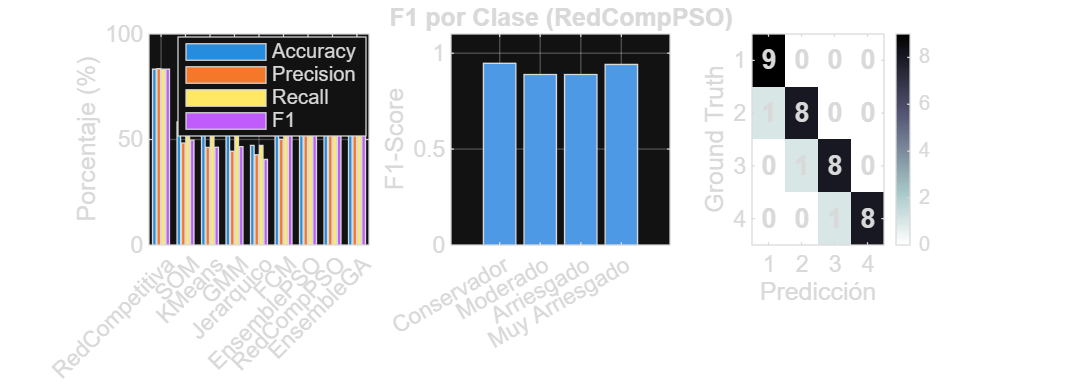

figure('Position', [50 50 1400 500], 'Color', 'w');

subplot(1,3,1);
metricas_plot = zeros(length(modelos_total), 4);
for m = 1:length(modelos_total)
    met = metricas_clasificacion.(modelos_total{m});
    metricas_plot(m,:) = [met.accuracy, met.precision_macro, met.recall_macro, met.f1_macro];
end
bar(metricas_plot * 100);
set(gca, 'XTickLabel', modelos_total, 'XTickLabelRotation', 45);
ylabel('Porcentaje (%)');
legend({'Accuracy', 'Precision', 'Recall', 'F1'}, 'Location', 'best');
grid on;

subplot(1,3,2);
bar(met_mejor.f1, 'FaceColor', [0.3 0.6 0.9]);
set(gca, 'XTickLabel', niveles_riesgo, 'XTickLabelRotation', 30);
ylabel('F1-Score');
title(sprintf('F1 por Clase (%s)', modelo_mejor));
ylim([0 1.1]);
grid on;

subplot(1,3,3);
imagesc(met_mejor.matriz_confusion);
colormap(flipud(bone)); colorbar;
set(gca, 'XTick', 1:K, 'YTick', 1:K);
xlabel('Predicción'); ylabel('Ground Truth');
for i = 1:K
    for j = 1:K
        text(j, i, num2str(met_mejor.matriz_confusion(i,j)), 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end
saveas(gcf, 'Fig2_Metricas_Clasificacion.png');

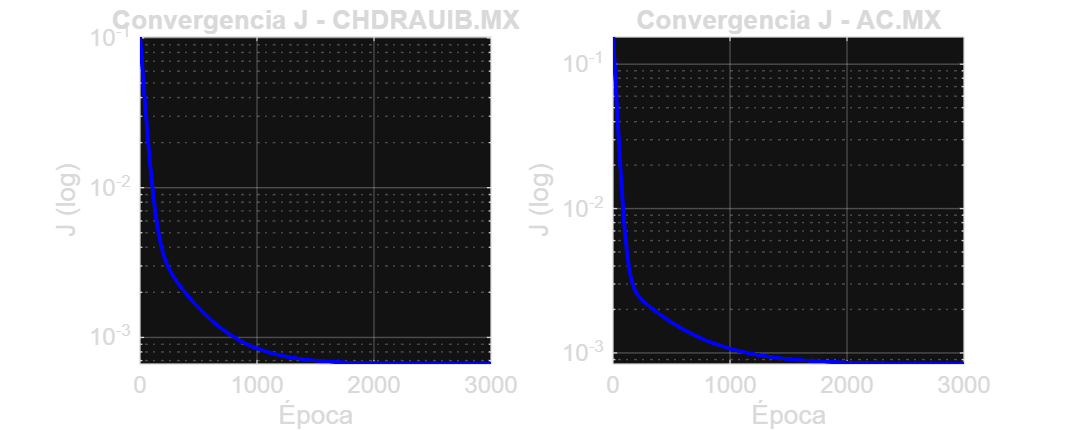


figure('Position', [50 50 1000 400], 'Color', 'w');
for a = 1:2
    campo = campos_pred{a};
    subplot(1,2,a);
    semilogy(historial_J.(campo), 'b-', 'LineWidth', 1.5);
    xlabel('Época'); ylabel('J (log)');
    title(sprintf('Convergencia J - %s', activos_sel{a}));
    grid on;
end
saveas(gcf, 'Fig3_Funcion_J.png');

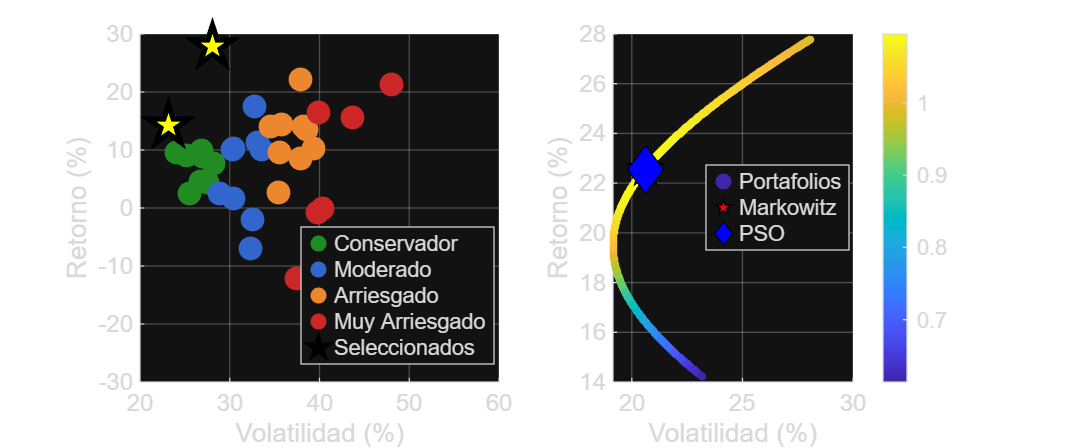

figure('Position', [50 50 1200 500], 'Color', 'w');

subplot(1,2,1); hold on;
for k = 1:K
    idx = (cluster_final == k);
    scatter(metricas(idx,1)*100, metricas(idx,2)*100, 80, colores(k,:), 'filled');
end
for i = 1:2
    idx = indices_sel(i);
    scatter(metricas(idx,1)*100, metricas(idx,2)*100, 250, 'y', 'p', 'filled', ...
        'MarkerEdgeColor', 'k', 'LineWidth', 2);
end
xlabel('Volatilidad (%)'); ylabel('Retorno (%)');
legend([niveles_riesgo, {'Seleccionados'}], 'Location', 'best');
grid on;

subplot(1,2,2);
scatter(resultados(:,2)*100, resultados(:,1)*100, 8, resultados(:,3), 'filled');
hold on;
scatter(vol_markowitz*100, ret_markowitz*100, 200, 'r', 'p', 'filled', 'MarkerEdgeColor', 'k');
scatter(vol_pso*100,      ret_pso*100,      150, 'b', 'd', 'filled', 'MarkerEdgeColor', 'k');
colormap(parula); colorbar;
xlabel('Volatilidad (%)'); ylabel('Retorno (%)');
legend({'Portafolios', 'Markowitz', 'PSO'}, 'Location', 'best');
grid on;
saveas(gcf, 'Fig4_Clustering_Frontera.png');

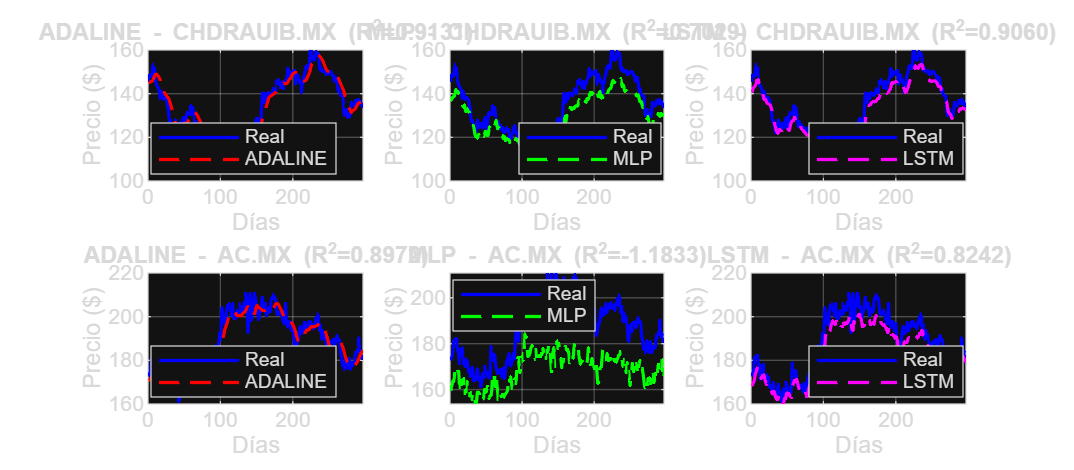


figure('Position', [50 50 1600 700], 'Color', 'w');

for a = 1:2
    campo = campos_pred{a};
    pred  = predicciones.(campo);

    subplot(2,3,(a-1)*3+1);
    plot(pred.real, 'b-', 'LineWidth', 1.2); hold on;
    plot(pred.pred_adaline, 'r--', 'LineWidth', 1.2);
    xlabel('Días'); ylabel('Precio ($)');
    met_a = metricas_prediccion.([campo '_ADALINE']);
    title(sprintf('ADALINE - %s (R^2=%.4f)', activos_sel{a}, met_a.R2));
    legend({'Real', 'ADALINE'}, 'Location', 'best');
    grid on;

    subplot(2,3,(a-1)*3+2);
    plot(pred.real, 'b-', 'LineWidth', 1.2); hold on;
    plot(pred.pred_mlp, 'g--', 'LineWidth', 1.2);
    xlabel('Días'); ylabel('Precio ($)');
    met_m = metricas_prediccion.([campo '_MLP']);
    title(sprintf('MLP - %s (R^2=%.4f)', activos_sel{a}, met_m.R2));
    legend({'Real', 'MLP'}, 'Location', 'best');
    grid on;

    subplot(2,3,(a-1)*3+3);
    plot(pred.real, 'b-', 'LineWidth', 1.2); hold on;
    plot(pred.pred_lstm, 'm--', 'LineWidth', 1.2);
    xlabel('Días'); ylabel('Precio ($)');
    met_l = metricas_prediccion.([campo '_LSTM']);
    title(sprintf('LSTM - %s (R^2=%.4f)', activos_sel{a}, met_l.R2));
    legend({'Real', 'LSTM'}, 'Location', 'best');
    grid on;
end

saveas(gcf, 'Fig5_Predicciones.png');

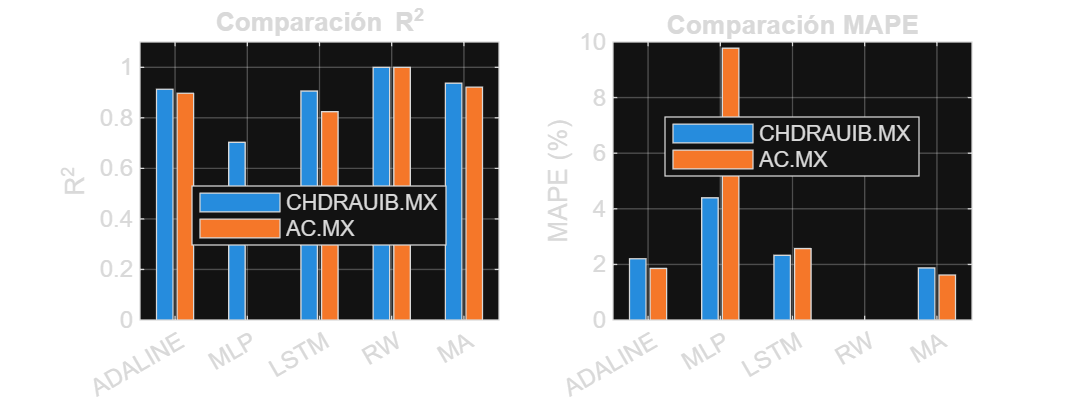


figure('Position', [50 50 1200 450], 'Color', 'w');

metodos    = {'ADALINE', 'MLP', 'LSTM', 'RW', 'MA'};
datos_r2   = zeros(2, 5);
datos_mape = zeros(2, 5);

for a = 1:2
    campo = campos_pred{a};
    for m = 1:5
        met = metricas_prediccion.([campo '_' metodos{m}]);
        datos_r2(a, m)   = met.R2;
        datos_mape(a, m) = met.MAPE;
    end
end

subplot(1,2,1);
bar(datos_r2');
set(gca, 'XTickLabel', metodos);
ylabel('R^2');
title('Comparación R^2');
legend(activos_sel, 'Location', 'best');
ylim([0 1.1]);
grid on;

subplot(1,2,2);
bar(datos_mape');
set(gca, 'XTickLabel', metodos);
ylabel('MAPE (%)');
title('Comparación MAPE');
legend(activos_sel, 'Location', 'best');
grid on;

saveas(gcf, 'Fig6_Comparacion_Prediccion.png');

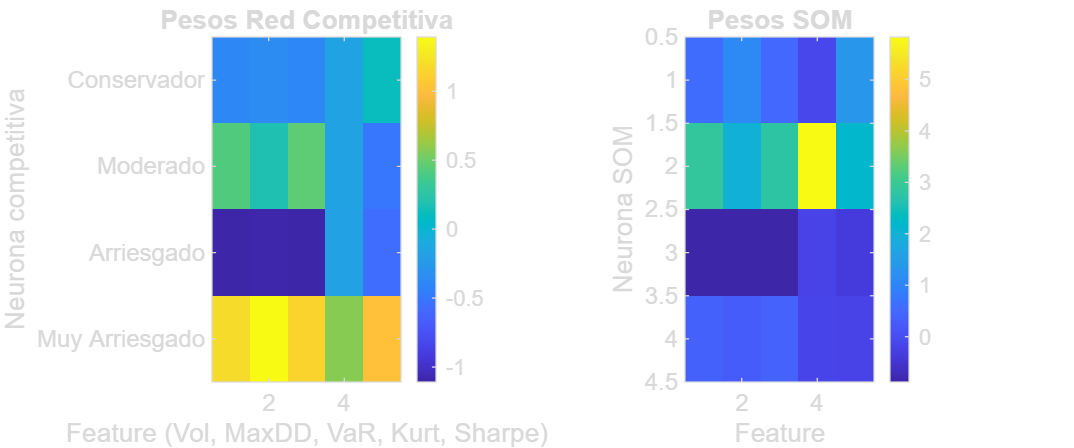


figure('Position', [50 50 1200 500], 'Color', 'w');

subplot(1,2,1);
imagesc(pesos_red_comp);
colorbar;
xlabel('Feature (Vol, MaxDD, VaR, Kurt, Sharpe)');
ylabel('Neurona competitiva');
title('Pesos Red Competitiva');
set(gca, 'YTick', 1:K, 'YTickLabel', niveles_riesgo);

subplot(1,2,2);
imagesc(pesos_som);
colorbar;
xlabel('Feature');
ylabel('Neurona SOM');
title('Pesos SOM');
saveas(gcf, 'Fig7_Pesos_Redes.png');

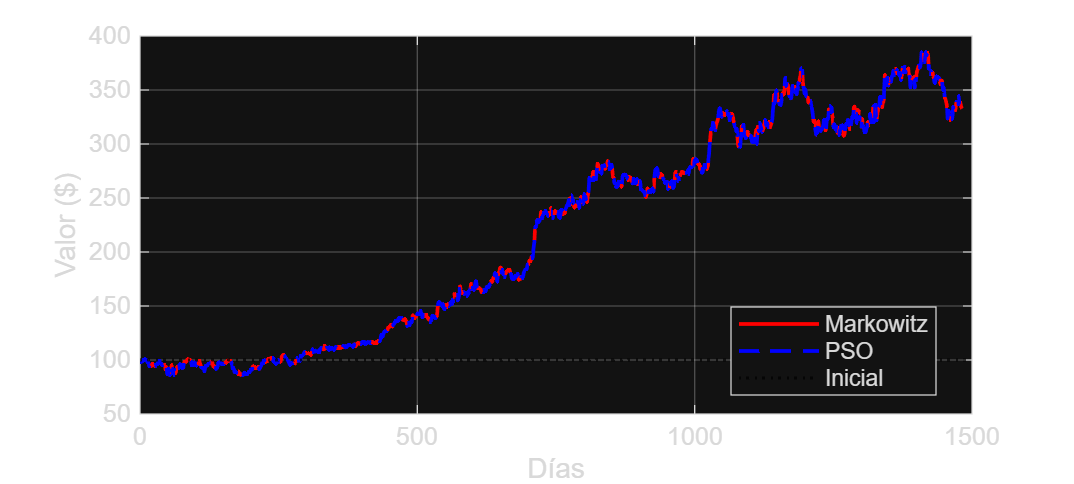

figure('Position', [50 50 1000 450], 'Color', 'w');
plot(valor_mark, 'r',  'LineWidth', 1.4); hold on;
plot(valor_pso,  'b--','LineWidth', 1.4);
yline(valor_inicial, 'k:', 'LineWidth', 1.1);
xlabel('Días'); ylabel('Valor ($)');
legend({'Markowitz', 'PSO', 'Inicial'}, 'Location', 'best');
grid on;
saveas(gcf, 'Fig8_Evolucion_Portafolio.png');

etiqueta_cluster = cell(num_acciones, 1);
for i = 1:num_acciones
    etiqueta_cluster{i} = niveles_riesgo{cluster_final(i)};
end

tabla_clustering_export = table( ...
    tickers', cluster_final, etiqueta_cluster, score_riesgo, ...
    metricas(:,1)*100, metricas(:,2)*100, metricas(:,3), metricas(:,4)*100, ...
    'VariableNames', {'Ticker', 'Cluster', 'Perfil', 'Score', 'Vol_pct', 'Ret_pct', 'Sharpe', 'MaxDD_pct'});
writetable(tabla_clustering_export, 'Resultados_Clustering.csv');
modelos_exp = modelos_total';
acc_exp     = zeros(length(modelos_total), 1);
prec_exp    = zeros(length(modelos_total), 1);
rec_exp     = zeros(length(modelos_total), 1);
f1_exp      = zeros(length(modelos_total), 1);
for m = 1:length(modelos_total)
    met         = metricas_clasificacion.(modelos_total{m});
    acc_exp(m)  = met.accuracy;
    prec_exp(m) = met.precision_macro;
    rec_exp(m)  = met.recall_macro;
    f1_exp(m)   = met.f1_macro;
end
tabla_clasif = table(modelos_exp, acc_exp*100, prec_exp*100, rec_exp*100, f1_exp, ...
    'VariableNames', {'Modelo', 'Accuracy', 'Precision', 'Recall', 'F1'});
writetable(tabla_clasif, 'Metricas_Clasificacion.csv');

activos_col = {}; metodo_col = {};
mse_col = []; rmse_col = []; mae_col = []; r2_col = []; mape_col = [];
for a = 1:2
    campo = campos_pred{a};
    for m = 1:5
        met = metricas_prediccion.([campo '_' metodos{m}]);
        activos_col{end+1,1} = activos_sel{a};
        metodo_col{end+1,1}  = metodos{m};
        mse_col(end+1,1)     = met.MSE;
        rmse_col(end+1,1)    = met.RMSE;
        mae_col(end+1,1)     = met.MAE;
        r2_col(end+1,1)      = met.R2;
        mape_col(end+1,1)    = met.MAPE;
    end
end
tabla_pred = table(activos_col, metodo_col, mse_col, rmse_col, mae_col, r2_col, mape_col, ...
    'VariableNames', {'Activo', 'Metodo', 'MSE', 'RMSE', 'MAE', 'R2', 'MAPE'});
writetable(tabla_pred, 'Metricas_Prediccion.csv');

fprintf('\nArchivos exportados.\n');


Archivos exportados.



function x_s = normalizar01(x)
    x_s = (x - min(x)) / (max(x) - min(x) + eps);
end

function [accuracy, precision, recall, f1, prec_macro, rec_macro, f1_macro, prec_w, rec_w, f1_w, mat_conf] = ...
    calcularMetricasClasificacion(y_true, y_pred, K)

    mat_conf = confusionmat(y_true, y_pred);
    precision = zeros(K, 1);
    recall    = zeros(K, 1);
    f1        = zeros(K, 1);
    support   = zeros(K, 1);

    for k = 1:K
        TP = mat_conf(k, k);
        FP = sum(mat_conf(:, k)) - TP;
        FN = sum(mat_conf(k, :)) - TP;

        if (TP + FP) > 0, precision(k) = TP / (TP + FP); end
        if (TP + FN) > 0, recall(k)    = TP / (TP + FN); end
        if (precision(k) + recall(k)) > 0
            f1(k) = 2 * precision(k) * recall(k) / (precision(k) + recall(k));
        end
        support(k) = sum(y_true == k);
    end

    accuracy   = sum(diag(mat_conf)) / sum(mat_conf(:));
    prec_macro = mean(precision);
    rec_macro  = mean(recall);
    f1_macro   = mean(f1);

    total_s = sum(support);
    prec_w  = sum(precision .* support) / total_s;
    rec_w   = sum(recall    .* support) / total_s;
    f1_w    = sum(f1        .* support) / total_s;
end

function cluster_mapeado = mapearClustersAGroundTruth(cluster_pred, y_true, K)
    cost_matrix = zeros(K,K);
    for i = 1:K
        for j = 1:K
            cost_matrix(i,j) = -sum((cluster_pred == i) & (y_true == j));
        end
    end

    mapeo = zeros(K,1);
    usado = false(K,1);
    for iter = 1:K
        mejor_val = inf; mejor_i = 0; mejor_j = 0;
        for i = 1:K
            if mapeo(i) == 0
                for j = 1:K
                    if ~usado(j) && cost_matrix(i,j) < mejor_val
                        mejor_val = cost_matrix(i,j);
                        mejor_i   = i;
                        mejor_j   = j;
                    end
                end
            end
        end
        mapeo(mejor_i) = mejor_j;
        usado(mejor_j) = true;
    end

    cluster_mapeado = zeros(size(cluster_pred));
    for i = 1:K
        cluster_mapeado(cluster_pred == i) = mapeo(i);
    end
end

function sharpe = calcularSharpe(w, mu, cov_mat)
    ret = w' * mu;
    vol = sqrt(w' * cov_mat * w);
    if vol > 0
        sharpe = ret / vol;
    else
        sharpe = -inf;
    end
end

function [X, y] = crearDatasetTemporal(precios, ventana)
    n = length(precios);
    X = zeros(n - ventana, ventana);
    y = zeros(n - ventana, 1);
    for i = 1:(n - ventana)
        X(i,:) = precios(i:i+ventana-1)';
        y(i)   = precios(i+ventana);
    end
end

function [X, y] = crearDatasetTemporalTest(precios_total, ventana, n_train)
    n_total = length(precios_total);
    n_test  = n_total - n_train;
    X       = zeros(n_test, ventana);
    y       = zeros(n_test, 1);
    for i = 1:n_test
        idx_ini = n_train - ventana + i;
        X(i,:)  = precios_total(idx_ini:idx_ini+ventana-1)';
        y(i)    = precios_total(n_train + i);
    end
end

function [w, b, historial_J] = entrenarADALINE_J(X, y, lr, epochs, lambda)
    [N, D] = size(X);
    w = randn(D,1) * 0.01;
    b = 0;
    historial_J = zeros(epochs,1);

    mejor_J = inf; mejor_w = w; mejor_b = b;
    paciencia = 100; contador = 0;

    for ep = 1:epochs
        y_pred = X * w + b;
        e      = y - y_pred;
        J      = 0.5 * mean(e.^2) + 0.5 * lambda * sum(w.^2);
        historial_J(ep) = J;

        if J < mejor_J
            mejor_J = J; mejor_w = w; mejor_b = b; contador = 0;
        else
            contador = contador + 1;
        end

        if contador >= paciencia
            break;
        end

        grad_w = -(X' * e) / N + lambda * w;
        grad_b = -mean(e);

        w = w - lr * grad_w;
        b = b - lr * grad_b;
    end

    w = mejor_w;
    b = mejor_b;
    historial_J = historial_J(1:ep);
end

function [J_train, J_test] = funcion_costo_J(X_train, y_train, X_test, y_test, w, b, lambda)
    e_train = y_train - (X_train * w + b);
    J_train = 0.5 * mean(e_train.^2) + 0.5 * lambda * sum(w.^2);

    e_test  = y_test - (X_test * w + b);
    J_test  = 0.5 * mean(e_test.^2)  + 0.5 * lambda * sum(w.^2);
end

function [mse, rmse, mae, r2, mape] = calcularMetricas(y_real, y_pred)
    mse  = mean((y_real - y_pred).^2);
    rmse = sqrt(mse);
    mae  = mean(abs(y_real - y_pred));

    ss_res = sum((y_real - y_pred).^2);
    ss_tot = sum((y_real - mean(y_real)).^2);
    r2     = 1 - ss_res/(ss_tot + eps);

    mape = mean(abs((y_real - y_pred) ./ (y_real + eps))) * 100;
end

function [mse_rw, rmse_rw, mae_rw, r2_rw, mape_rw, ...
          mse_ma, rmse_ma, mae_ma, r2_ma, mape_ma] = ...
          baselinesSerie(precios, ventana, n_train, min_p, max_p)

    den_p = max_p - min_p;
    if den_p == 0
        den_p = 1;
    end

    precios_n = (precios - min_p) / den_p;
    [~, y_rw] = crearDatasetTemporalTest(precios_n, ventana, n_train);
    y_real    = y_rw * den_p + min_p;

    y_pred_rw = precios(n_train+1:end);
    y_pred_rw = y_pred_rw(1:length(y_real));
    [mse_rw, rmse_rw, mae_rw, r2_rw, mape_rw] = calcularMetricas(y_real, y_pred_rw);

    y_pred_ma = zeros(size(y_real));
    for i = 1:length(y_real)
        idx_g = n_train + i;
        if idx_g-ventana+1 < 1
            y_pred_ma(i) = mean(precios(1:idx_g));
        else
            y_pred_ma(i) = mean(precios(idx_g-ventana+1:idx_g));
        end
    end
    [mse_ma, rmse_ma, mae_ma, r2_ma, mape_ma] = calcularMetricas(y_real, y_pred_ma);
end

function [pesos_opt, cl_opt, acc_opt, sil_opt] = optimizarRedCompetitiva_PSO(X_norm, y_true, K)
    [~, D]  = size(X_norm);
    n_part  = 20;
    max_iter = 50;

    particulas  = 0.1 + 2.9 * rand(n_part, D);
    velocidades = zeros(n_part, D);

    mejor_local     = particulas;
    mejor_local_fit = -inf(n_part,1);
    mejor_global    = zeros(1,D);
    mejor_global_fit = -inf;

    warning('off', 'all');

    for i = 1:n_part
        fit_i = evaluar_red_comp(particulas(i,:), X_norm, y_true, K);
        mejor_local_fit(i) = fit_i;
        if fit_i > mejor_global_fit
            mejor_global_fit = fit_i;
            mejor_global     = particulas(i,:);
        end
    end

    for iter = 1:max_iter
        w_in = 0.9 - 0.5 * iter / max_iter;
        for i = 1:n_part
            velocidades(i,:) = w_in * velocidades(i,:) + ...
                2.05 * rand(1,D) .* (mejor_local(i,:) - particulas(i,:)) + ...
                2.05 * rand(1,D) .* (mejor_global - particulas(i,:));

            particulas(i,:) = max(min(particulas(i,:) + velocidades(i,:), 3.0), 0.1);

            fit_i = evaluar_red_comp(particulas(i,:), X_norm, y_true, K);
            if fit_i > mejor_local_fit(i)
                mejor_local_fit(i) = fit_i;
                mejor_local(i,:)   = particulas(i,:);
            end
            if fit_i > mejor_global_fit
                mejor_global_fit = fit_i;
                mejor_global     = particulas(i,:);
            end
        end
    end

    warning('on', 'all');

    pesos_opt = mejor_global;
    X_pond    = X_norm .* pesos_opt;

    red = competlayer(K);
    red.trainParam.epochs     = 500;
    red.trainParam.showWindow = false;
    red = train(red, X_pond');

    cl_opt = vec2ind(red(X_pond'))';
    cl_opt = mapearClustersAGroundTruth(cl_opt, y_true, K);

    acc_opt = mean(cl_opt == y_true);
    sil_opt = mean(silhouette(X_norm, cl_opt));
end

function fit = evaluar_red_comp(pesos, X_norm, y_true, K)
    X_pond = X_norm .* pesos;

    red = competlayer(K);
    red.trainParam.epochs     = 300;
    red.trainParam.showWindow = false;
    red = train(red, X_pond');

    cl = vec2ind(red(X_pond'))';
    cl = mapearClustersAGroundTruth(cl, y_true, K);
    fit = mean(cl == y_true);
end

function [pesos_opt, cl_opt, acc_opt, sil_opt] = optimizarEnsambleClustering_GA(matriz_clusters, X_norm, y_true, K)
    [~, n_alg] = size(matriz_clusters);
    n_pob      = 60;
    n_gen      = 40;

    poblacion = rand(n_pob, n_alg);
    fitness   = zeros(n_pob, 1);

    for i = 1:n_pob
        fitness(i) = fitness_ensemble_ga(poblacion(i,:), matriz_clusters, X_norm, y_true, K);
    end

    for gen = 1:n_gen
        [~, idx_ord] = sort(fitness, 'descend');
        elite        = poblacion(idx_ord(1:2), :);

        nueva_pob = elite;
        while size(nueva_pob, 1) < n_pob
            idx_p = randsample(n_pob, 2, true, fitness/sum(fitness));
            p1    = poblacion(idx_p(1), :);
            p2    = poblacion(idx_p(2), :);

            if rand < 0.8
                pt = randi([1, n_alg-1]);
                h1 = [p1(1:pt), p2(pt+1:end)];
                h2 = [p2(1:pt), p1(pt+1:end)];
            else
                h1 = p1; h2 = p2;
            end

            if rand < 0.2
                h1 = max(h1 + 0.1 * randn(1, n_alg), 0);
            end
            if rand < 0.2
                h2 = max(h2 + 0.1 * randn(1, n_alg), 0);
            end

            nueva_pob = [nueva_pob; h1; h2]; 
        end
        poblacion = nueva_pob(1:n_pob, :);

        for i = 1:n_pob
            fitness(i) = fitness_ensemble_ga(poblacion(i,:), matriz_clusters, X_norm, y_true, K);
        end
    end

    [~, idx_best] = max(fitness);
    pesos_opt     = poblacion(idx_best, :);
    pesos_opt     = pesos_opt / sum(pesos_opt);

    cl_opt = ensamblar_clusters(pesos_opt, matriz_clusters, K);
    acc_opt = mean(cl_opt == y_true);
    sil_opt = mean(silhouette(X_norm, cl_opt));
end

function fit = fitness_ensemble_ga(pesos, matriz_clusters, X_norm, y_true, K)
    if sum(pesos) == 0
        pesos = rand(size(pesos));
    end
    pesos = max(pesos, 0);
    pesos = pesos / sum(pesos);

    cl  = ensamblar_clusters(pesos, matriz_clusters, K);
    fit = mean(cl == y_true) + 0.05 * mean(silhouette(X_norm, cl));
end

function cl = ensamblar_clusters(pesos, matriz_clusters, K)
    [n_obs, n_mod] = size(matriz_clusters);
    puntaje        = zeros(n_obs, K);

    for m = 1:n_mod
        for k = 1:K
            puntaje(:, k) = puntaje(:, k) + pesos(m) * (matriz_clusters(:, m) == k);
        end
    end

    [~, cl] = max(puntaje, [], 2);
end

function [cl_opt, pesos_opt, hist_pso] = optimizarEnsembleClusteringPSO(matriz_clusters, X_norm, y_true)
    [~, n_mod] = size(matriz_clusters);
    K          = numel(unique(y_true));

    n_part   = 50;
    max_iter = 200;

    particulas = rand(n_part, n_mod);
    particulas = particulas ./ sum(particulas, 2);
    velocidades = zeros(n_part, n_mod);

    fitness_p = zeros(n_part, 1);
    for i = 1:n_part
        fitness_p(i) = fitness_ensemble_pso(particulas(i,:), matriz_clusters, X_norm, y_true, K);
    end

    pbest     = particulas;
    pbest_fit = fitness_p;
    [gbest_fit, idx_best] = max(pbest_fit);
    gbest     = pbest(idx_best, :);
    hist_pso  = zeros(max_iter, 1);

    for it = 1:max_iter
        w_in = 0.9 - 0.5 * it / max_iter;
        for i = 1:n_part
            velocidades(i,:) = w_in * velocidades(i,:) + ...
                2.05 * rand(1, n_mod) .* (pbest(i,:) - particulas(i,:)) + ...
                2.05 * rand(1, n_mod) .* (gbest - particulas(i,:));

            particulas(i,:) = max(particulas(i,:) + velocidades(i,:), 0.01);
            particulas(i,:) = particulas(i,:) / sum(particulas(i,:));

            fit_i = fitness_ensemble_pso(particulas(i,:), matriz_clusters, X_norm, y_true, K);
            if fit_i > pbest_fit(i)
                pbest(i,:)   = particulas(i,:);
                pbest_fit(i) = fit_i;
                if fit_i > gbest_fit
                    gbest     = particulas(i,:);
                    gbest_fit = fit_i;
                end
            end
        end
        hist_pso(it) = gbest_fit;
    end

    pesos_opt = gbest';
    cl_opt    = ensamblar_clusters(gbest, matriz_clusters, K);
end

function fit = fitness_ensemble_pso(pesos, matriz_clusters, X_norm, y_true, K)
    pesos = max(pesos, 0);
    pesos = pesos / (sum(pesos) + eps);

    cl = ensamblar_clusters(pesos, matriz_clusters, K);
    fit = mean(cl == y_true) + 0.1 * mean(silhouette(X_norm, cl));
end